# **Homework 2 2021/2022  Esposito Crescenzo (**Matricola N. 0124002375)

1.**  Interpolazione**

Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale $f$sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *ezplot *per osservarne il grafico. 

format long
%Stabilisco gli estremi del mio intervallo
a=0;b=5;
%Scelgo la mia funzione
funrif= @(x) exp(-x).*(cos(4*x/2-pi/2)).^2+(5./(1+2*x.^2).*cos(2*x)-3)

funrif = function_handle with value:
    @(x)exp(-x).*(cos(4*x/2-pi/2)).^2+(5./(1+2*x.^2).*cos(2*x)-3)


figure(1)
%Genero il grafico della mia funzione
fplot(funrif,[a,b])
hold on
grid on 

Definire quindi un insieme di $m$ punti $P=\{(x_i,y_i)\}_{i=1}^m$ con $11 \leq m \leq 21, m \in \mathbb{N}$. Le ascisse di $P$ sono linearmente distribuite in $[a,b]$, le ordinate sono i corrispondenti valori assunti dalla valutazione di $f(x)$.

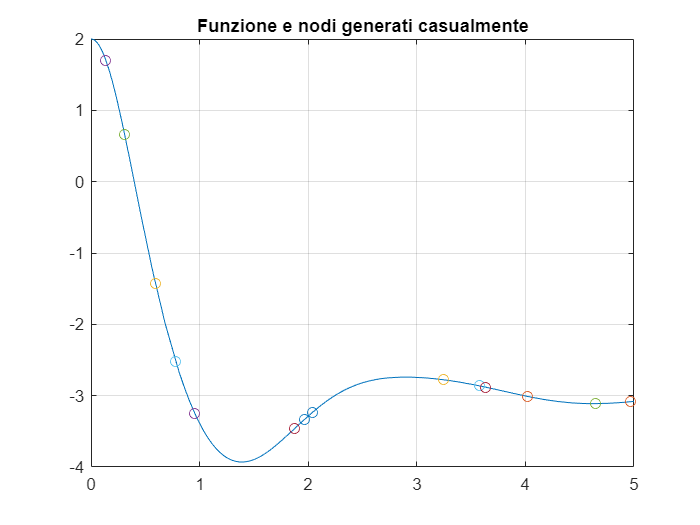

m=14;
%Genero m ascisse, settando come range gli estremi del mio intervallo
rng(0,'v5normal');
x= (b-a).*rand(m,1)+a;
%Dopo aver trovato m ascisse ricavo m ordinate
%Avendo m coppie di ascisse e ordinate posso visualizzare i miei punti sul
%grafico
y=zeros(m,1);
for i=1:m
    y(i,1) = funrif(x(i));
     plot (x(i),y(i), 'o')
end
title('Funzione e nodi generati casualmente')

1.1. Definire un insieme $\mathcal{F}$di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio $p$  $\in$ $\mathcal{F}$ che interpola $f$ nei nodi $x_i$. Costruire e risolvere il relativo sistema lineare $Ba=y$ (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice $B$.


%Genero la matrice b scegliendo come insieme F l’insieme dei polinomi di
%grado al più m-1

B = ones(length(x));

for i = 2:length(x)
  B(:, i) = x .* B(:, i-1);  
end
B=fliplr(B);

%Usare il metodo di gauss con pivoting
ax=Sgauss_pivot(B,y)

ax =   -0.000332514759700
   0.010147616862017
  -0.135729399101233
   1.042434675730999
  -5.050888763235078
  15.910413270058646
 -32.015844366761812
  36.973325461674733
 -11.556269924971488
 -33.063537671837700



%Calcolo l'indice di condizionamento della mia matrice
cond(B)

ans =      3.688255546562804e+14


        1.2. Valutare il polinomio $p$ su una griglia di $N$ punti di valutazione distribuiti casualmente in $[a,b]$. Fissare $N\,\,( 201 \leq N \leq 399)$. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.

%Fisso il parametro N
N=300;
figure(2)
grid on;
hold on
axis ([0 5.5 -4 2.2])
xx = linspace(a,b,N);
curva = polyval(ax,xx);
fplot(funrif,[a,b])
plot(x,y,'o');
plot(xx,curva,'r',LineStyle='--');
title('Polinomio Interpolante')

%Calcolo gli errori dell'interpolazione polinomiale
errPolinomio = abs(funrif(xx) - curva)

errPolinomio =    0.213878569899013   0.160295868320041   0.117081095507991   0.082741418534771   0.055922128222353   0.035404618540550   0.020102761254849   0.009057852725654   0.001432333610863   0.003497501112103   0.006349575460879   0.007644661624544   0.007815343796761   0.007215108343866   0.006127370395963   0.004774269602345   0.003325093316409   0.001904212505544   0.000598442948281   0.000536229328217   0.001468594812739   0.002186853788946   0.002693931246971   0.003003452537954   0.003136346121651   0.003118030150701   0.002976132967608   0.002738693561688   0.002432786290091   0.002083514332628   0.001713318046813   0.001341547257179   0.000984250222035   0.000654136280021   0.000360673740059   0.000110289236491   0.000093360636191   0.000249070191334   0.000357738678508   0.000422014343188   0.000445941974165   0.000434624367494   0.000393905493338   0.000330080882038   0.000249638826210   0.000159034400101   0.000064496995047   0.000028128970521   0.000113511318766   0.

errNormPol=norm(errPolinomio)

errNormPol =    0.631134467721559


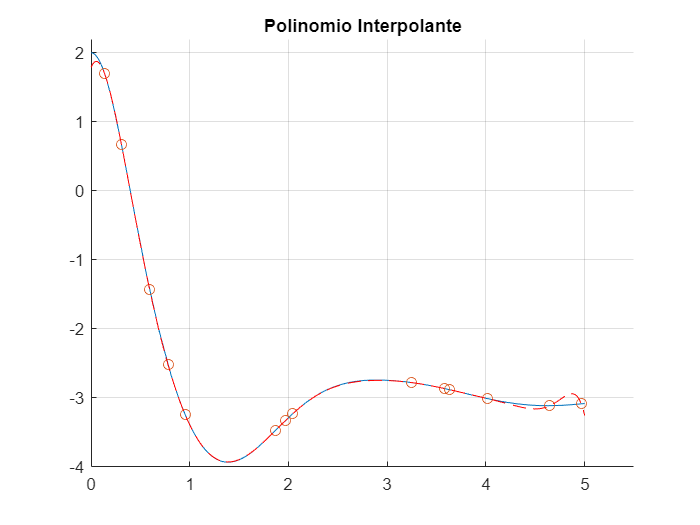

hold off

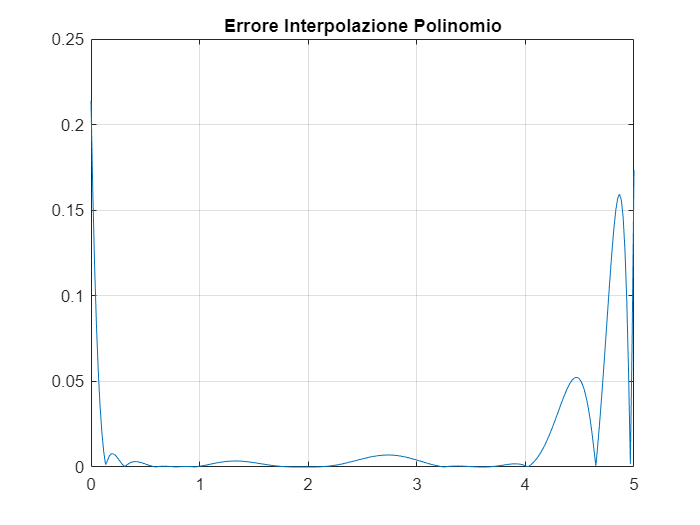

plot(xx,errPolinomio)
grid on
title('Errore Interpolazione Polinomio')

        1.3. Interpolare i punti $P$ mediante una spline $s$ di terzo grado di tipo *not-a-knot*.  Valutare l'interpolante ottenuto sulla una griglia di $N$ punti di valutazione.

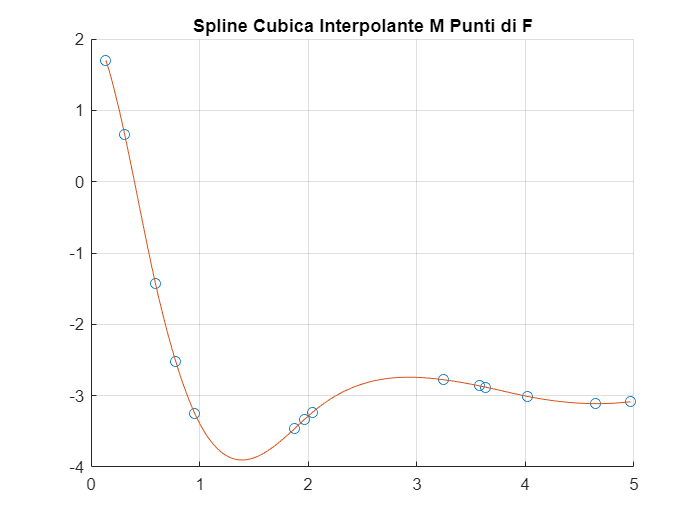

figure(3)
hold on
grid on
xx= linspace(min(x),max(x),N);
yspline=spline(x,y,xx);
plot(x,y,'o',xx,yspline)
title('Spline Cubica Interpolante M Punti di F')

        1.4. Fissare un valore $n\,\,( 10 \leq n \leq 19)$ e definire un nuovo insieme di punti $Q = \{(x_j, y_j)\}_{j=1}^n$ le cui ascisse sono i nodi di Chebyshev in $[a,b]$ e le cui ordinate sono i valori corrispondenti assunti da $f(x)$. Costruire il polinomio interpolante i punti $Q$ e valutarlo sulla griglia di valutazione generata al punto 1.2.

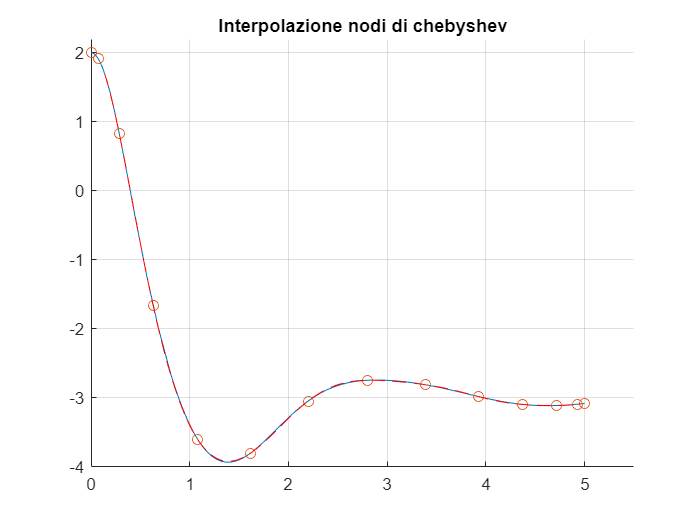

n=14;
%Calcolo dei nodi Chebyshev
nodicheb = AscisseCheb(a,b,n);
valori = funrif(nodicheb);

figure(4)
grid on
hold on
axis ([0 5.5 -4 2.2])

fplot(funrif,[a,b])
curva2 = polyval(polyfit(nodicheb,valori,length(nodicheb)-1),xx);
plot(nodicheb,valori,'o');
plot(xx,curva2,'r',LineStyle='--');
title('Interpolazione nodi di chebyshev')
hold off

        1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.

%Calcolo gli errori dell'interpolazione di chebyshev
errorech = abs(funrif(xx) - curva2)

errorech =    0.004058024901116   0.004717813687635   0.005112163582662   0.005214488794509   0.005017037479532   0.004528599334064   0.003771912539777   0.002780917722327   0.001597986417123   0.000271230372880   0.001148023246519   0.002607526298696   0.004056128557572   0.005445493364379   0.006731497671716   0.007875317126813   0.008844207460896   0.009612001733793   0.010159349064057   0.010473724554965   0.010549242447530   0.010386305356255   0.009991122039863   0.009375124787834   0.008554315406503   0.007548566183783   0.006380899288915   0.005076764983355   0.003663335911530   0.002168831708704   0.000621885285052   0.000949040524628   0.002516179681467   0.004052928930092   0.005534250839388   0.006937013303348   0.008240266271351   0.009425457597112   0.010476590792267   0.011380328165148   0.012126043340377   0.012705827512130   0.013114454005305   0.013349305824205   0.013410270876836   0.013299609491547   0.013021798707205   0.012583357631188   0.011992657934838   0.0112


%Confronto le due norme
errNormCh=norm(errorech);
errTable = table(errNormPol,errNormCh)

errTable = 1×2 table
       errNormPol            errNormCh    
    _________________    _________________

    0.631134467721559    0.119616246171185


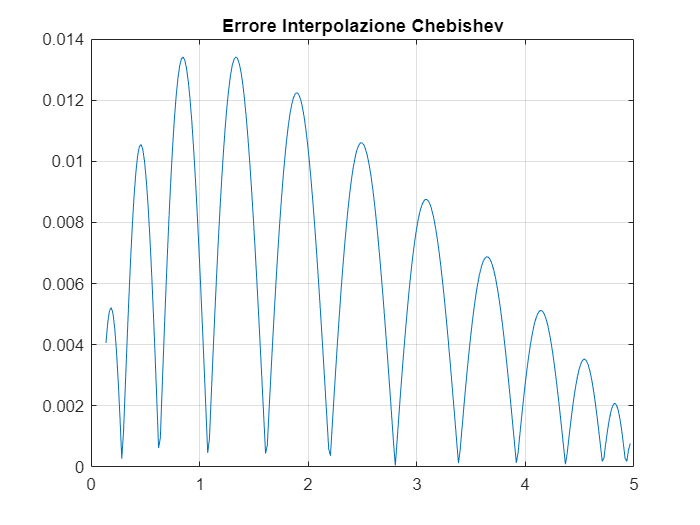

plot(xx,errorech)
title('Errore Interpolazione Chebishev')
grid on

     1.6. Considerare il poligono di $N$vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando `fill, `visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.

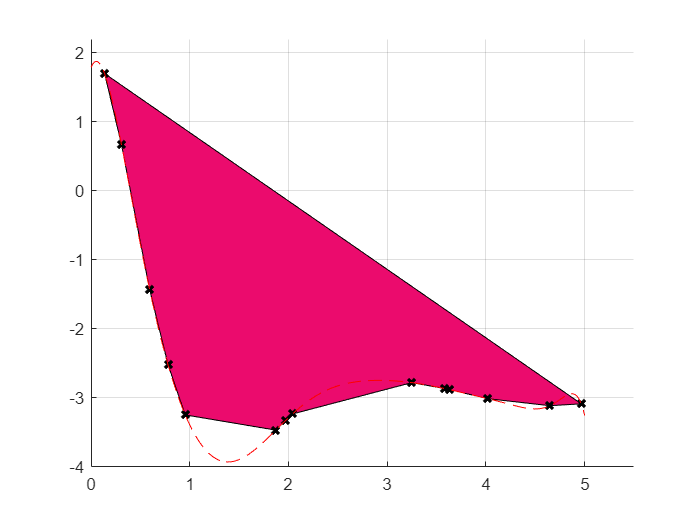

figure (5)
hold on 
grid on
axis ([0 5.5 -4 2.2])
xx = linspace(a,b,N);
%Inserisco x e y in una matrice
mat=[x,y];
% ordino la prima colonna, quella delle ascisse
[~,idx] = sort(mat(:,1)); 
% ordino l'intera matrice usando l'indice di ordinamento, cosi da ripristinare le coppie ascisse ordinate originali
sortedmat = mat(idx,:);  
fill(sortedmat(:,1),sortedmat(:,2),[rand rand rand])
plot(x,y,'x','LineWidth',2,Color='black');
plot(xx,curva,'r',LineStyle='--');

 2.** Interpolazione di curve parametriche**

  Si considerino le seguenti curve parametriche:

         3. $x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

Campionare la curva in $n$ punti $P=\{(x_i,y_i)\}_{i=1}^n$, corrispondenti a $n$ punti $t_i$ equispaziati nell'intervallo $[a,b]$ in cui varia il parametro $t$ (fissare $20<n<30$). 

n=22;
%scelgo la curva 3
funrifx= @(t) t.*cos(t);
funrify= @(t) t.*sin(t);

%Genero n parametri, settando come range gli estremi del mio intervallo
%iniziale
rng(0,'v5normal');
at=-2*pi;bt=2*pi;
t= (bt-at).*rand(n,1)+at;
xC=funrifx(t);
yC=funrify(t);

  2.1. costruire due spline parametriche $p_x$ e $p_y$ che interpolino rispettivamente i punti $(t_i,x_i)$ e i punti $(t_i, y_i)$  ($i = 1,\ldots, n$);

  2.2.  valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.

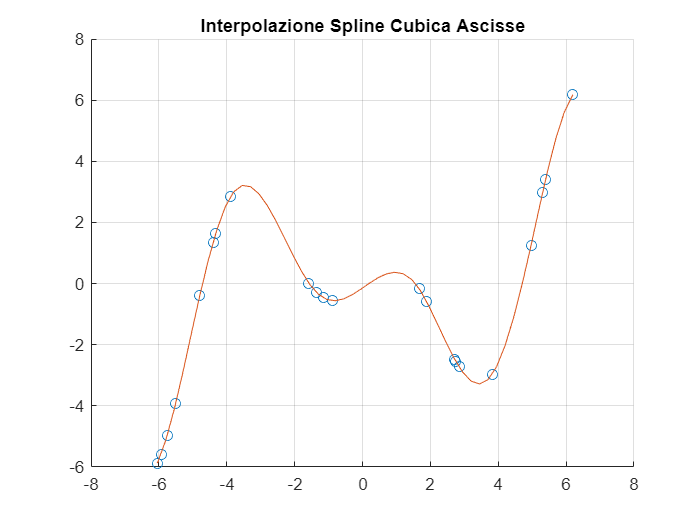

figure (6)
hold on
grid on
%Calcolo Spline Ascisse
tt= linspace(min(t),max(t),50);
pxC= spline(t,xC,tt);
plot(t,xC,'o',tt,pxC)
title('Interpolazione Spline Cubica Ascisse')

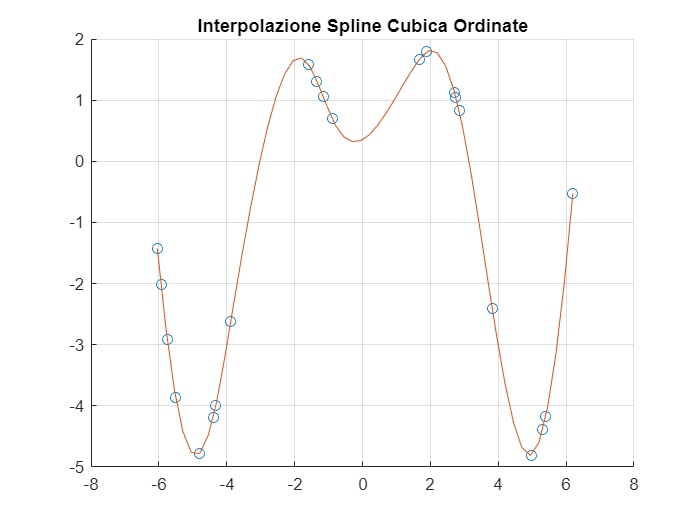

figure (7)
hold on
grid on
%Calcolo Spline Ordinate
pyC= spline(t,yC,tt);
plot(t,yC,'o',tt,pyC)
title('Interpolazione Spline Cubica Ordinate')

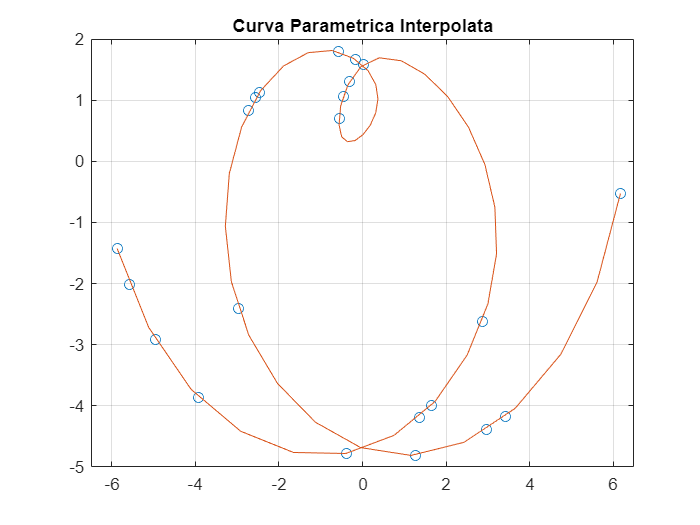

figure(20)
plot(xC,yC,'o',pxC,pyC)
axis([-6.5 6.5 -5 2])
grid on
title('Curva Parametrica Interpolata')

    2.3.  Ripetere i punti (2.1) e (2.2) su un insieme di $m=40$ punti $S = \{(x_j,y_j)\}_{j=1}^m$ le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando `ginput` usato su una immagine a propria scelta oppurtunamente caricata (usare `imread). `Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che `x` e `y` siano i vettori delle coordinate dei vertici di un poligono (chiuso). 

m=40;
%ginput(m) %seleziono i miei m punti con ginput e salvo il risultato il un
%file dat
figure(8);
hold on
%Carico l'immagine scelta
img=imread('telegram.png');
image(img)
set(gca,'YDir','reverse');
%Carico la matrice contenente le coordinate dei punti selezionati con
%ginput
MTg=1.0e+02 *readmatrix("matrix.dat")

MTg = 1.0e+02 *

   0.826774193548387   1.316258278145695
   0.667096774193549   1.255860927152318
   0.542903225806452   1.220894039735099
   0.505806451612903   1.198642384105960
   0.509032258064516   1.173211920529801
   0.526774193548387   1.141423841059603
   0.623548387096774   1.100099337748345
   0.728387096774194   1.058774834437086
   0.833225806451613   1.011092715231788
   0.968709677419355   0.966589403973510


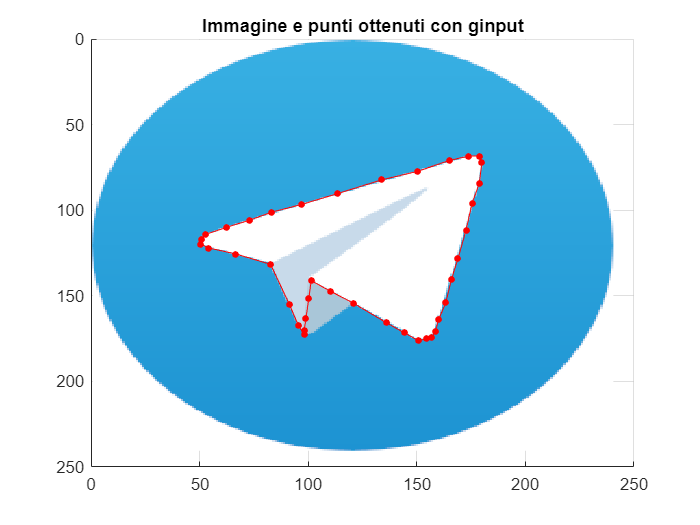

%Evidenzio sul grafico i nodi e li unisco graficamente
plot(MTg(:,1),MTg(:,2),'o',MarkerSize=2,Color='r',LineWidth=2)
plot(MTg(:,1),MTg(:,2),'r')

figure (8)
hold on
grid on
title('Immagine e punti ottenuti con ginput')

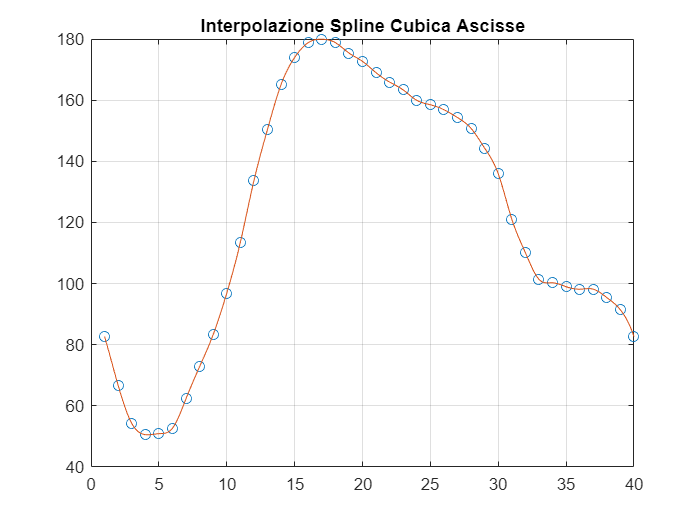

figure(13)
%Calcolo Spline Ascisse Immagine
t=1:length(MTg(:,1));
tt = linspace(t(1),t(end),500);
pxTg= spline(t,MTg(:,1),tt);
plot(t,MTg(:,1),'o',tt,pxTg)
grid on
title('Interpolazione Spline Cubica Ascisse')

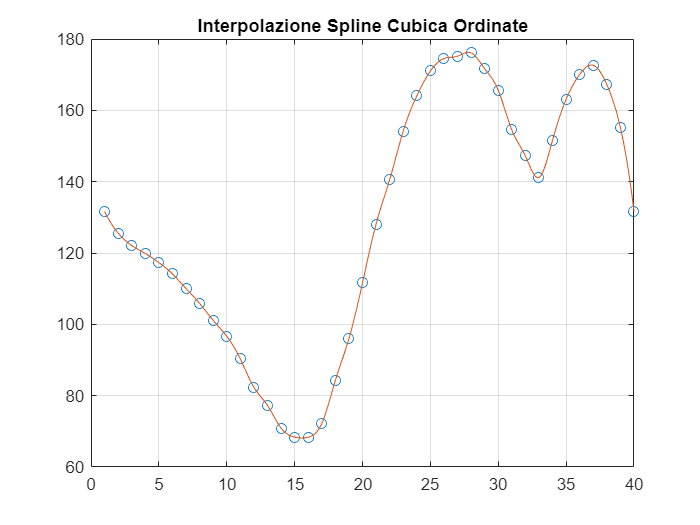

%Calcolo Spline Ordinate Immagine
pyTg= spline(t,MTg(:,2),tt);
plot(t,MTg(:,2),'o',tt,pyTg)
grid on
title('Interpolazione Spline Cubica Ordinate')

       2.4. Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file `.mlx`

%Calcolo del perimetro con la function CalcoloPerimetro, calcola le
%distanze fra i vari punti ordinati
PTg=CalcoloPerimetro(MTg(:,1),MTg(:,2))

PTg =      4.266831797538724e+02


%Verifica Perimetro Con Funzioni Integrate Matlab
figure(9)
set(gca,'YDir','reverse');
grid on
hold on
polyin = polyshape(MTg(:,1),MTg(:,2));
plot(polyin)
axis equal
perimeter(polyin)

ans =      4.266831797538725e+02


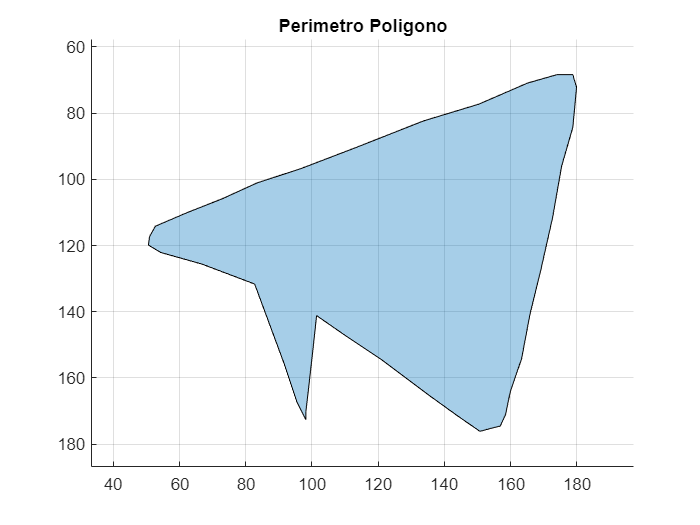

title('Perimetro Poligono')

       2.5. Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.

figure(10)
set(gca,'YDir','reverse');
hold on
grid on  
%cubiche di hermite
xch = pchip(t,MTg(:,1),tt);
ych = pchip(t,MTg(:,2),tt);
norm(ych,inf)

ans =      1.761264628522691e+02


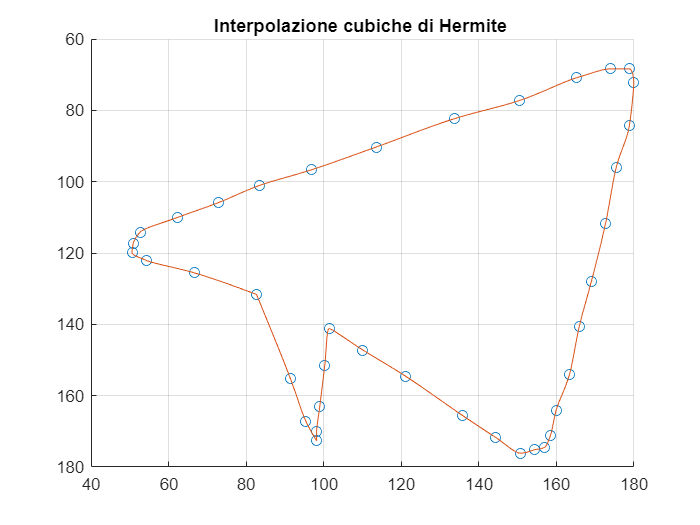

plot(MTg(:,1),MTg(:,2),'o',xch,ych)
title('Interpolazione cubiche di Hermite ')

3. **Approssimazione**

Scaricare il dataset dell'andamento del covid da [https://github.com/pcm-dpc/COVID-19](https://github.com/pcm-dpc/COVID-19)

Caricare il dataset in matlab utilizzando il comando `readtable`.

%Carico il dataset trovato su github
dataset = readtable('andamento.csv')

dataset = 835×24 table
           data             stato     ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati    isolamento_domiciliare    totale_positivi    variazione_totale_positivi    nuovi_positivi    dimessi_guariti    deceduti    casi_da_sospetto_diagnostico    casi_da_screening    totale_casi    tamponi    casi_testati         note         ingressi_terapia_intensiva    note_test    note_casi    totale_positivi_test_molecolare    totale_positivi_test_antigenico_rapido    tamponi_test_molecolare    tamponi_test_antigenico_rapido
    ___________________<

Generare un insieme di punti $C=\{(t_i,y_i)\}_{i=1}^n$ le cui ascisse il tempo $t_1,t_2,\ldots,t_n$. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella. Scegliere inoltre $5 \leq n \leq 11$.

         3.1 Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.

%Inizializzo la xCovid come indice temporale, indica infatti il numero di
%giorni dall'inizio della raccolta dati
xCovid = [1,2,3,4,5,6,7];
%Carico i valori dei positivi nei primi 7 giorni
Buffer = dataset.("totale_positivi");
yCovid=zeros(1,7);
for i=1:7
    yCovid(i) = Buffer(i);
end

3.2. Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti

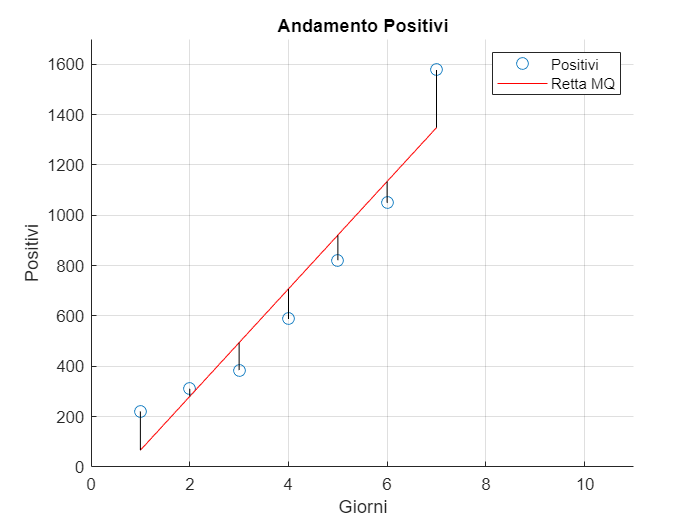

figure(11)
grid on
hold on
axis ([0 11 0 1700])
xx = linspace(0,8, 100);
%marker sui valori
plot(xCovid,yCovid,'o','MarkerSize',7)
title('Andamento Positivi')
aCovid = polyfit(xCovid,yCovid,1);
%calcolo il residuo della retta dei minimi quadrati
xrange = [min(xCovid),max(xCovid)];
resids = abs(yCovid - polyval(aCovid,xCovid));


plot(xrange,polyval(aCovid,xrange),'-r')
%evidenzio gli scostamenti, distanza punto-retta
plot(repmat(xCovid(:),[1 2])',[yCovid(:),polyval(aCovid,xCovid(:))]','k-')
legend('Positivi','Retta MQ')

xlabel("Giorni")
ylabel("Positivi")

3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.

figure(14)
grid on
hold on
plot(xCovid,yCovid,'o','MarkerSize',7)
%Generatore di polinomi per l'approssimazione, dal grado 2 al grado 10 dal
%7 in poi mi avvisa che il grado del polinomio ha raggiunto il numero di
%nodi
norma=zeros(1,10);
norma(1)=norm(resids(1,:));

for i=2:10
    a2Covid = polyfit(xCovid,yCovid,i);
    %matrice 10x7 con i residui, le righe sono i vari gradi del polinomio
    %le colonne i vari punti
    resids(i,:) = abs(yCovid - polyval(a2Covid,xCovid));
    norma(1,i)=norm(resids(i,:));
    curvaMQ=polyval(a2Covid,xx);
    plot(xx,curvaMQ)
end

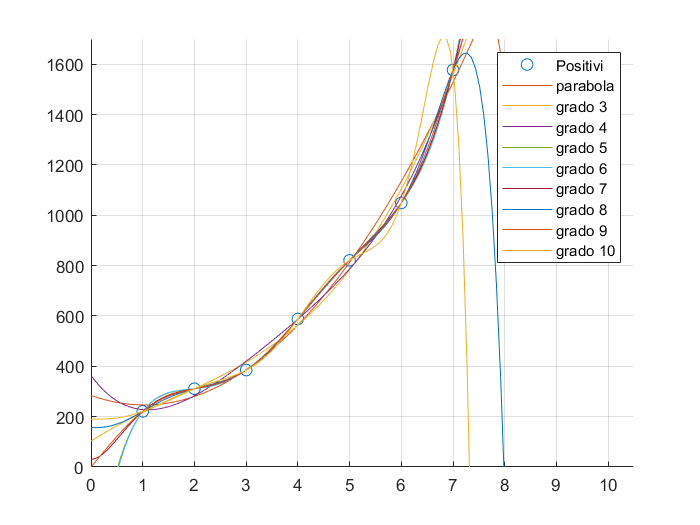

axis ([0 10.5 0 1700])
xx = linspace(0,8, 100);
legend('Positivi' ,'parabola','grado 3','grado 4','grado 5','grado 6','grado 7','grado 8','grado 9','grado 10')

      3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.

%Residui
resids

resids = 1.0e+02 *

   1.542857142857140   0.307142857142854   1.088571428571431   1.194285714285716   1.000000000000002   0.855714285714287   2.288571428571426
   0.254761904761907   0.307142857142855   0.010000000000001   0.243809523809523   0.078571428571428   0.855714285714284   0.490952380952381
   0.048571428571427   0.003809523809524   0.313333333333333   0.243809523809523   0.381904761904761   0.552380952380954   0.187619047619046
   0.069870129870156   0.280173160173161   0.352813852813852   0.006926406926403   0.342424242424240   0.276017316017324   0.069177489177464
   0.000346320346633   0.002077922077900   0.005194805194800   0.006926406926403   0.005194805194825   0.002077922077829   0.000346320346521
   0.000000000000042   0.000000000000028   0.000000000000022   0.000000000000008   0.000000000000038   0.000000000000041   0.000000000000045
   0.000000000000775   0.000000000000066   0.000000000000036   0.000000000000007   0.000000000000036   0.000000000000030   0.000000000

%Norma 2 dei valori dei residui
norma

norma = 1.0e+02 *

   3.472154539022873   1.094640623783939   0.803847888951280   0.637283194608075   0.010527227119355   0.000000000000091   0.000000000000848   0.000000000001586   0.000000000000661   0.000000000001821


.

4. **Quadratura**

    4.1. Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in $[a,b]$. Usare la funzione `ezplot` per stabilire l'intervallo $[a,b]$; 

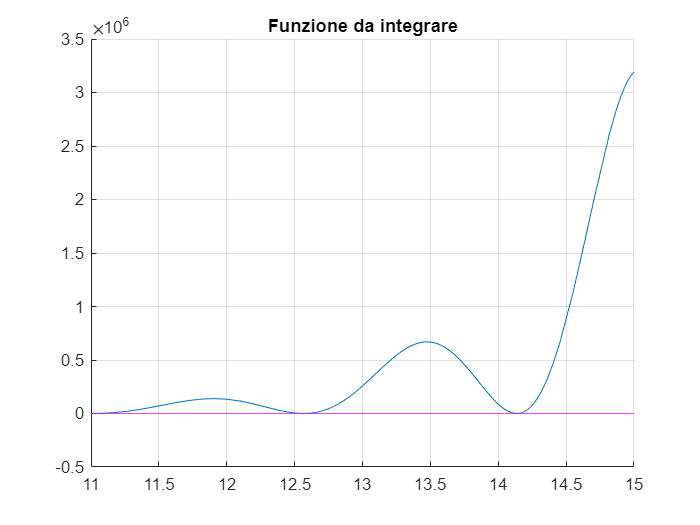

%definisco la funzione composta, definita, positiva e continua in [a,b]
funrif3= @(x) exp(x).*(cos(4*x/2-pi/2)).^2+(5./(1+2*x.^2).*cos(2*x)-3);
figure(12)
hold on
grid on
yline(0,'-','color','m')
fplot(funrif3,[11,15])
title('Funzione da integrare')

    4.2. Considerare come valore esatto dell'integrale $I=I[f]=\int_a^b f(x)dx$ il valore ottenuto mediante la funzione MATLAB `integral` con tolleranza $10^{-9}$;

val_esatto = integral(funrif3,11,15,'AbsTol',1e-9)

val_esatto =      1.815244425289893e+06


%Setto gli estremi
a2=11;b2=15;

    4.3. Stimare l'integrale $I$ utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su $1, 2,$ e $3$ nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione.

%Formula Rettangolare
Rett=Rettangolare(funrif3,a2,b2,100);
errRett=abs(Rett-val_esatto);
%Formula del Punto Medio
PuntM=PuntoMedio(funrif3,a2,b2,100);
errPuntM=abs(PuntM-val_esatto);
%Formula Trapezoidale
Trapez=Trapezoidale(funrif3,a2,b2,100);
errTrapez=abs(Trapez-val_esatto);
%Formula di Simpson
Simps=Simpson(funrif3,a2,b2,100);
errSimps=abs(Simps-val_esatto);
Stime = table(val_esatto,Rett,PuntM,Trapez,Simps) 

Stime = 1×5 table
       val_esatto             Rett               PuntM               Trapez              Simps      
    ________________    ________________    ________________    ________________    ________________

    1815244.42528989    1750938.01864734    1815162.90355379    1815407.33798096    1772591.90854171


Errore = table(errRett,errPuntM,errTrapez,errSimps)

Errore = 1×4 table
        errRett             errPuntM           errTrapez            errSimps    
    ________________    ________________    ________________    ________________

    64306.4066425499    81.5217360996176    162.912691064877    42652.5167481781


    4.4. **Costruzione di formule di quadratura. **Fissare $p$ $3 \leq p \leq 5$ nodi distinti, **non** **equispaziati**, $x_i \in [0,4]$  di una formula di quadratura 

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

    per il calcolo numerico dell'integrale definito della funzione $f$ in $[0,4]$;

%Fisso p a mia scelta
p=5;
%Fisso l'intervallo [a,b]
a=0;b=4;
%Con la funzione rand genero i nodi
xt=(b-a)*rand(p,1)+a;
%Ordino i nodi con la funzione sort
xt = sort(xt);



for i=1:p
    Integr(i,1) = ((xt(end)^i-xt(1)^i)/i);
end
%Calcolo la matrice di vandermonde
Mat2 = [ones(size(xt)) xt xt.^2 xt.^3 xt.^4]

Mat2 =    1.000000000000000   1.269777618348598   1.612335200059039   2.047307150310576   2.599624797349420
   1.000000000000000   1.505300352349877   2.265929150784664   3.410903949076013   5.134434916375710
   1.000000000000000   1.550094218924641   2.402792087543594   3.724554124179196   5.773409815962102
   1.000000000000000   1.907996331341564   3.640450000412869   6.945965245220151  13.252876205506057
   1.000000000000000   2.591088901273906   6.713741694304816  17.395901590133079  45.074327537846905


Mat2=fliplr(Mat2)

Mat2 =    2.599624797349420   2.047307150310576   1.612335200059039   1.269777618348598   1.000000000000000
   5.134434916375710   3.410903949076013   2.265929150784664   1.505300352349877   1.000000000000000
   5.773409815962102   3.724554124179196   2.402792087543594   1.550094218924641   1.000000000000000
  13.252876205506057   6.945965245220151   3.640450000412869   1.907996331341564   1.000000000000000
  45.074327537846905  17.395901590133079   6.713741694304816   2.591088901273906   1.000000000000000


    4.5.  Determinare i valori dei pesi $w_i$ affinché la formula risulti esatta per polinomi algebrici di grado al più $p-1$ (costruire e risolvere il sistema $B^Tw=I$.)

%Calcolo i pesi
w = Mat2\Integr

w = 1.0e+03 *

   0.417656334086326
  -3.057307589680243
   8.190843250757087
  -9.519254594966064
   4.055770774161516


%Sommatoria dei pesi moltiplicati per la funzione in un determinato punto
Quad = w(1)*funrif3(xt(1))+w(2)*funrif3(xt(2))+w(3)*funrif3(xt(3))+w(4)*funrif3(xt(4))+w(5)*funrif3(xt(5))

Quad =      1.846963111373088e+04


function perimetro=CalcoloPerimetro(x,y)
punti=[x y];%punti ordinati  
perimetro = 0;
for i = 1:size(punti, 1)-1
perimetro = perimetro + norm(punti(i, :) - punti(i+1, :));
end
perimetro = perimetro + norm(punti(end, :) - punti(1, :)); % Dall'ultimo punto al primo
end

function [A,b]= TriangGauss_pivot(A,b)
% triangolarizzazione di Gauss in
% place, con pivoting parziale,
% a parallelismo sui dati.
% Determina il sistema Ux=p equivalente
% al sistema dato Ax=b
% U e' triangolare superiore ed e'
% memorizzata nel triangolo superiore
% di A; p e‘ memorizzato in b.
n = size(A,1);
for k=1:n-1
    % pivoting parziale
    [pivot,ind_piv] = max(abs(A(k:n,k)));
    ind_piv = ind_piv+k-1; % spiazzamento
    if pivot == 0
        error('matrice singolare');
    else
       %scambio righe
        A([k ind_piv],k:n)=A([ind_piv k],k:n);
        b([k ind_piv]) = b([ind_piv k]);
        % eliminazione
        for i=k+1:n
            molt = A(i,k)/A(k,k);
            A(i,k+1:n) = A(i,k+1:n)-molt*A(k,k+1:n);
            b(i) = b(i)-molt*b(k);  
        end
    end
end
end

function x = Sgauss_pivot(A,b)
% risoluzione di un sistema di eq.
% lineari con il metodo di Gauss
% (con pivoting parziale)
% input:
% A matrice dei coefficienti
% (inalterata in output)
% b vettore dei termini noti
% (inalterato in output)
% output:
% x soluzione
%
[A,b] = TriangGauss_pivot(A,b);
x = STriangSup(A,b);
end

function x = STriangSup(U,b)
% risoluzione di un sistema di eq.
% lineari triangolare superiore
% (backward substitution)
% La matrice dei coefficienti U e’
% memorizzata in formato standard
n = size(U,1); 
x = zeros(size(b));
if any(diag(U)==0)
    disp('matrice singolare')
end
x(n) = b(n)/U(n,n);
for i=n-1:-1:1
    x(i)=(b(i)-U(i,i+1:n)*x(i+1:n))/(U(i,i));
end
end

    
function Qf = Rettangolare (f,a,b,n)
h = (b-a)/(n-1);
breaks = a+h*(0:n-1);
f_breaks = f(breaks);
Qf = h*sum(f_breaks(1:end-1));
end



function Qf = PuntoMedio (f,a,b,n)
h = (b-a)/(n-1);
breaks = a+h*(0:n-1);
puntimedi = (breaks(1:end-1)+breaks(2:end))/2;
f_pmedi = f(puntimedi);
Qf = h*sum(f_pmedi);
end

function Qf = Trapezoidale (f,a,b,n)
h = (b-a)/(n-1);
breaks = a+h*(0:n-1);
f_breaks = f(breaks);
Qf = h*(0.5*f_breaks(1)+sum(f_breaks(2:end-1))+0.5*f_breaks(end));
end

function Qf = Simpson (f,a,b,n)
hbar = (b-a)/(n-1);
tuttinod = a+hbar*(0:n-1);
puntmedi = tuttinod(2:2:end-1);
estr_sott = tuttinod(3:2:end-1);
f_puntmedi = f(puntmedi);
f_estr_sott = f(estr_sott);
fa = f(a); fb = f(b);
Qf = (hbar/3)*(fa+4*sum(f_puntmedi)+2*sum(f_estr_sott)+fb);
end

function xc = AscisseCheb(a,b,n)
% calcola n nodi di Chebychev per l'intervallo [a,b]
xc1 =cos((0:n-1)*pi/(n-1)); % nodi in [-1,1]
xc = 0.5*(a+b)+0.5*(b-a)*xc1; % nodi in [a,b]
xc = xc(end:-1:1); % i nodi di Chebychev vengono ordinati da -1 a 1
end

